Load a sample from MNIST dataset

load("mnist.mat")

idx = 23053;

x = reshape (X(: , idx) , [28 28]).' ;
label = labels (idx) ;

Visualize the loaded sample

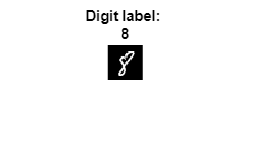

figure;
imshow(x,[]);
title(["Digit label: ", num2str(label)]);

Blurring by convolution with K matrix

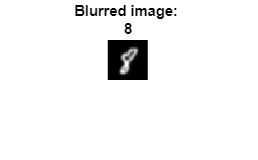

n = -2:2;

Z = 0; % normalization constant
for m1 = n
    for m2 = n
        Z = Z + exp(-(m1^2+m2^2)/2);
    end
end

K = zeros(5, 5);

for n1 = n % kernel matrix
    for n2 = n
        K(n1+3, n2+3) = 1/Z*exp(-(n1^2+n2^2)/2);
    end
end

y = conv2(x, K);

figure;
imshow(y,[]);
title(["Blurred image: ", num2str(label)]);

Obtain a matrix A that will have the same affect with 2d convolution when multiplied by x using "lazy man's method"

x_vec = x(:);

[height_x, width_x] = size(x);
x_vec_size = numel(x_vec);
y_vec_size = numel(y(:));

A = zeros(y_vec_size, x_vec_size);

for i = 1:x_vec_size
    temp_x = zeros(height_x, width_x);
    temp_x(i) = 1; 

    temp_y = conv2(temp_x, K); 

    A(:, i) = temp_y(:)';
end

y_vec = A * x_vec;
norm(y - reshape(y_vec , [32 32]))

ans = 1.1060e-13

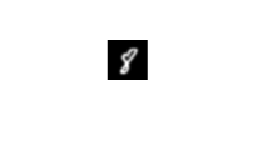

imshow(reshape(y_vec , [32 32]),[]);

Obtaining original sample by using Moore Penrose pseuode-inverse with vectorized y

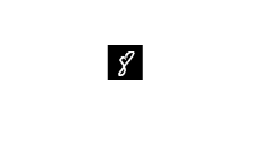

x_mnls_tilde = pinv(A)*y_vec;
imshow(reshape(x_mnls_tilde,  [height_x width_x]), []);


diff_image = x - reshape(x_mnls_tilde, [height_x, width_x]);
mse = mean(diff_image(:).^2);

Adding gaussian white noise

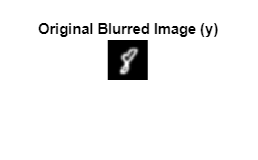

w = randn(size(y)); 
y_tilde = y + w;

figure;
imshow(y, []);
title('Original Blurred Image (y)');

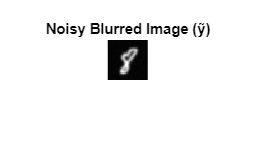


figure;
imshow(y_tilde, []);
title('Noisy Blurred Image (ỹ)');


numerator = norm(y_tilde(:) - y(:));
denominator = norm(y(:));
normalized_difference = numerator / denominator

normalized_difference = 0.0196

Using pseudo-inverse to obtain the x from y with gaussian noie

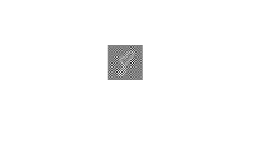

x_mnls_tilde = pinv(A)*y_tilde(:);
imshow(reshape(x_mnls_tilde,  [height_x width_x]), []);


diff_image = x - reshape(x_mnls_tilde, [height_x, width_x]);
mse = mean(diff_image(:).^2)

mse = 6.7758e+04

Observing singular values

[U, S, V] = svd(A);
singular_values = diag(S);
singular_values_A_pseudo = 1 ./ singular_values;
k_A = max(singular_values) / min(singular_values);

fprintf('Condition Number (kappa(A)): %e\n', k_A);

Condition Number (kappa(A)): 1.775351e+03


fprintf('Singular Values of A: \n');

Singular Values of A: 


disp(singular_values);

    0.9897
    0.9744
    0.9744
    0.9594
    0.9494
    0.9494
    0.9348
    0.9348
    0.9154
    0.9154
    0.9108
    0.9013
    0.9013
    0.8782
    0.8782
    0.8733
    0.8733
    0.8598
    0.8598
    0.8467
    0.8377
    0.8377
    0.8241
    0.8241
    0.8114
    0.8114
    0.8077
    0.8077
    0.7906
    0.7906
    0.7705
    0.7691
    0.7691
    0.7622
    0.7622
    0.7573
    0.7573
    0.7378
    0.7378
    0.7271
    0.7271
    0.7114
    0.7114
    0.7098
    0.7098
    0.6988
    0.6988
    0.6862
    0.6809
    0.6809
    0.6786
    0.6786
    0.6565
    0.6565
    0.6475
    0.6475
    0.6404
    0.6404
    0.6375
    0.6375
    0.6263
    0.6263
    0.6211
    0.6211
    0.5989
    0.5989
    0.5977
    0.5910
    0.5910
    0.5836
    0.5836
    0.5746
    0.5746
    0.5713
    0.5713
    0.5599
    0.5599
    0.5516
    0.5516
    0.5398
    0.5398
    0.5391
    0.5391
    0.5197
    0.5197
    0.5150
    0.5150
    0.5117
    0.5117
    0.5090
    0.5032

fprintf('Singular Values of A† (Pseudo-Inverse): \n');

Singular Values of A† (Pseudo-Inverse): 


disp(singular_values_A_pseudo);

   1.0e+03 *

    0.0010
    0.0010
    0.0010
    0.0010
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0011
    0.0012
    0.0012
    0.0012
    0.0012
    0.0012
    0.0012
    0.0012
    0.0012
    0.0012
    0.0012
    0.0012
    0.0013
    0.0013
    0.0013
    0.0013
    0.0013
    0.0013
    0.0013
    0.0013
    0.0013
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0015
    0.0015
    0.0015
    0.0015
    0.0015
    0.0015
    0.0015
    0.0015
    0.0015
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0017
    0.0017
    0.0017
    0.0017
    0.0017
    0.0017
    0.0017
    0.0017
    0.0017
    0.0018
    0.0018
    0.0018
    0.0018
    0.0018
    0.0018
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0019
    0.0020
    0.0020
    0.0

Using regularization to counter noise amplification due too pseudo-inverse

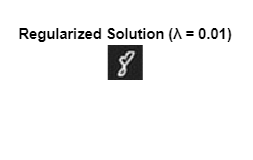

lambda = 0.01; % best = 0.0013

x_reg = (A' * A + lambda * eye(size(A, 2))) \ (A' * y_tilde(:));

x_reg_image = reshape(x_reg, [height_x, width_x]);
figure;
imshow(x_reg_image, []);
title(['Regularized Solution (λ = ', num2str(lambda), ')']);


reg_error = norm(x_reg - x(:)) / norm(x(:))

reg_error = 0.2394

Obtain z by downsampling y

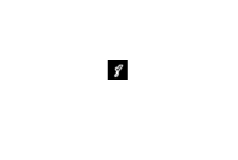

z = y(1 : 2 : end, 1 : 2 : end);

figure;
imshow(z,[]);

Obtaining a B matrix which is the counterpart of A marix found before for the downsampled z

[height_z, width_z] = size(z);
z_vec_size = numel(z);

B = zeros(z_vec_size, x_vec_size);

for i = 1:x_vec_size
    temp_x = zeros(height_x, width_x);
    temp_x(i) = 1; 

    temp_z = conv2(temp_x, K);
    temp_z = temp_z(1 : 2 : end, 1 : 2 : end);

    B(:, i) = temp_z(:)';
end

z_vec = B * x_vec;
norm(z - reshape(z_vec , [16 16]))

ans = 5.8545e-14

imshow(reshape(z_vec , [16 16]),[]);

Obtaining x with pseudo-inverse from z

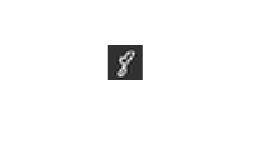

x_mnls_tilde = pinv(B)*z_vec;
imshow(reshape(x_mnls_tilde,  [height_x width_x]), []);


diff_image = x - reshape(x_mnls_tilde, [height_x, width_x]);
mse = mean(diff_image(:).^2);